Discussion HW3

**Introduction**

A skateboarder is moving along a curved path. The path is a section of circle of radius R = 10 m. The equation of motion is


$$\frac{d^2 \phi }{{\mathrm{dt}}^2 }+\frac{g}{R}\sin \phi =0$$


where φ is an appropriately chosen angular coordinate. This equation has no closed form solution. It must be solved numerically. The initial conditions are  ̇φi = 0, and φi = either 10 or 70 deg (see below).

**Problems**

**(A)** (This part is not graded) Take some time to think about this problem and make these predictions first, based on whatever you know about physics and common sense; no detailed derivations required:

(1) Do you expect the skateboarder to oscillate back and forth with either set of initial conditions (yes, no)?

With phi equal to 0 we should see no oscillations as sin of phi would be 0. Any phi greater than 0 should cause oscillations.

(2) Do you expect that if the skateboarder starts at any initial φi they will oscillate back to that same amplitude after one period? (same, not same)?

It should be the same because there is no frictional or drag component affecting the motion.

(3) Do you expect the period of oscillation to be independent of the φi (period independent of φi, period dependent on φi)?

Yes

**(B)** Write down the Euler-Cromer finite difference solution to this ODE. Be sure to identify the general term a(t) (as presented in HW2) with its explicit expression in this case.


$$\begin{array}{l}
\frac{d^2 \phi }{{\mathrm{dt}}^2 }+\frac{g}{R}\sin \phi =0\\
\frac{d^2 \phi }{{\mathrm{dt}}^2 }=-\frac{g}{R}\sin \phi \\
\frac{\overset{\ldotp }{\phi} \left(t+\Delta t\right)-\overset{\ldotp }{\phi} \left(t\right)}{\Delta t}=-\frac{g}{R}\sin \phi \\
\overset{\ldotp }{\phi} \left(t+\Delta t\right)=\overset{\cdot }{\phi} \left(t\right)-\Delta t\frac{g}{R}\sin \phi 
\end{array}$$


**(C)** In the Discussion we explained that ODE45 uses two 1st order ODEs to replace the single 2nd order ODE. Identify the equivalent of these two equations in the finite difference relations of part B.

The first order ODE is,


$$\overset{\ldotp }{\phi} \left(t\right)$$


The second order ODE is,


$$\overset{\ldotp }{\phi} \left(t+\Delta t\right)=\overset{\cdot }{\phi} \left(t\right)-\Delta t\frac{g}{R}\sin \phi$$


**(D)** Write code to solve Equation 1 . You can use the code guidance posted on Canvas under Discussion 3. Use a total time span of 100 s. Plot the motion of the skateboarder, that is, φ(t) in degrees (not radians), over the first 30 s for each set of initial conditions.

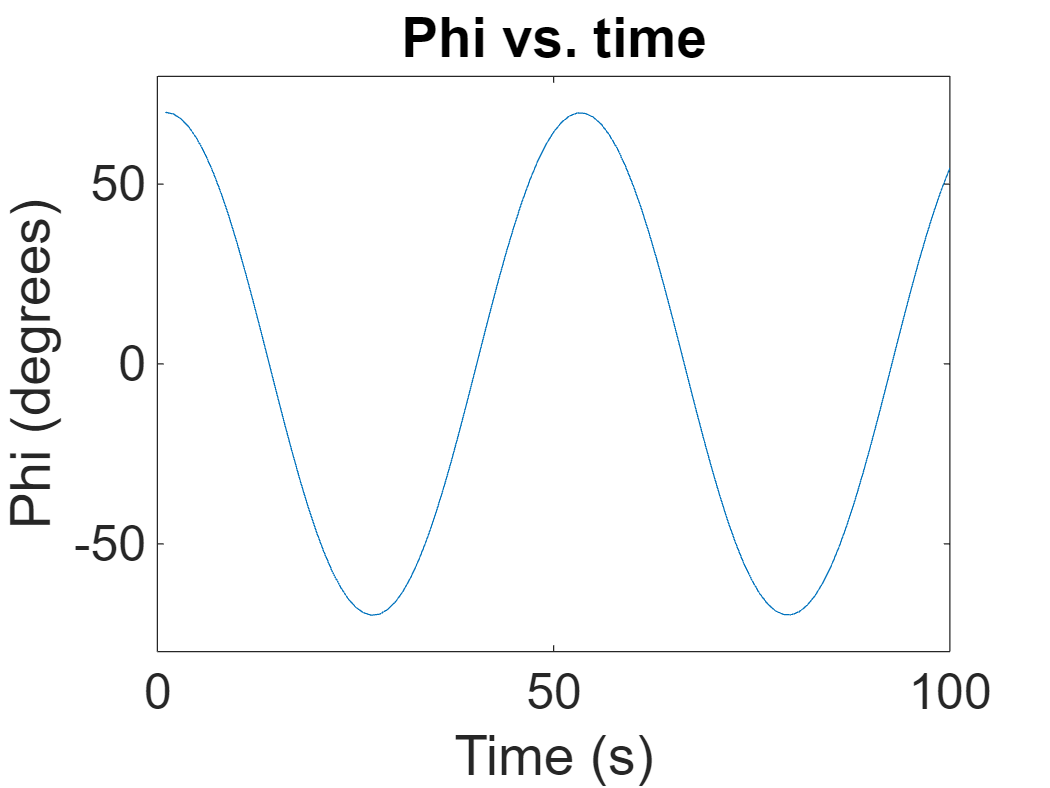

tspan = linspace(1, 100, 100) ;
iphi = 70 ;
iphidot = 0 ;
    function phidot = odefun(t, phi)
    g = 10 ;
    R = 10 ;
    phidot(1) = phi(2) ;
    phidot(2) = -g/R*sind(phi(1)) ;
    phidot = phidot' ;
end

[t, phi] = ode45(@odefun, tspan, [iphi, iphidot]) ;
plot(t, phi(:, 1))
title('Phi vs. time') ;
ylabel('Phi (degrees)') ;
xlabel('Time (s)') ;
set(gca, 'fontsize', 20)
xlim([0, 100]) ;
ylim([-80, 80]) ;

**(E) **Now you must check that your solution makes sense. How do you propose to check your solution here. Please answer without going to the next page. You are not graded on this part, and there is no right or wrong answer.

I would check by treating the skateboarder as a (classic) simple harmonic oscillator and comparing the plots.

**(F)** One way to check your solution is to compare it to the solution of a classic harmonic oscillator (HO). Add to your livescript code that calculates φHO(t) for the classic harmonic oscillator that has the same parameters and the same two sets of initial conditions as used earlier. Overplot these results in the earlier Figures.


$$\begin{array}{l}
x\left(t\right)=x_0 \sin \left(\omega t+\phi \right)\\
v_{\max } =A\omega \\

\end{array}$$


ix = 70
x = ix*sin(w*tspan)